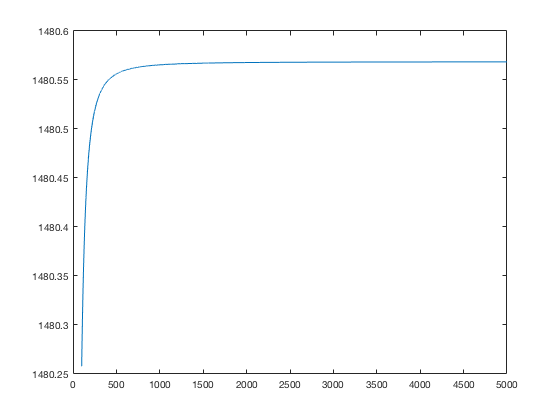

clear all
clc
close all

N = 100:5000;
area = 100:5000;

for n = min(N):max(N)
    dx = 30/n;
    sum = 0;
    for i = 1:n
        x = (i-1)*dx;
        x1 = x+dx;
        sum = sum + ((((200*x/(5+x))*exp(-2*x/30))) + (((200*x1/(5+x1))*exp(-2*x1/30))))*dx/2;
    end
    area(n-99) = sum;
end

plot(N,area)